# Wind Turbine Aerodynamics

## Simplified representation

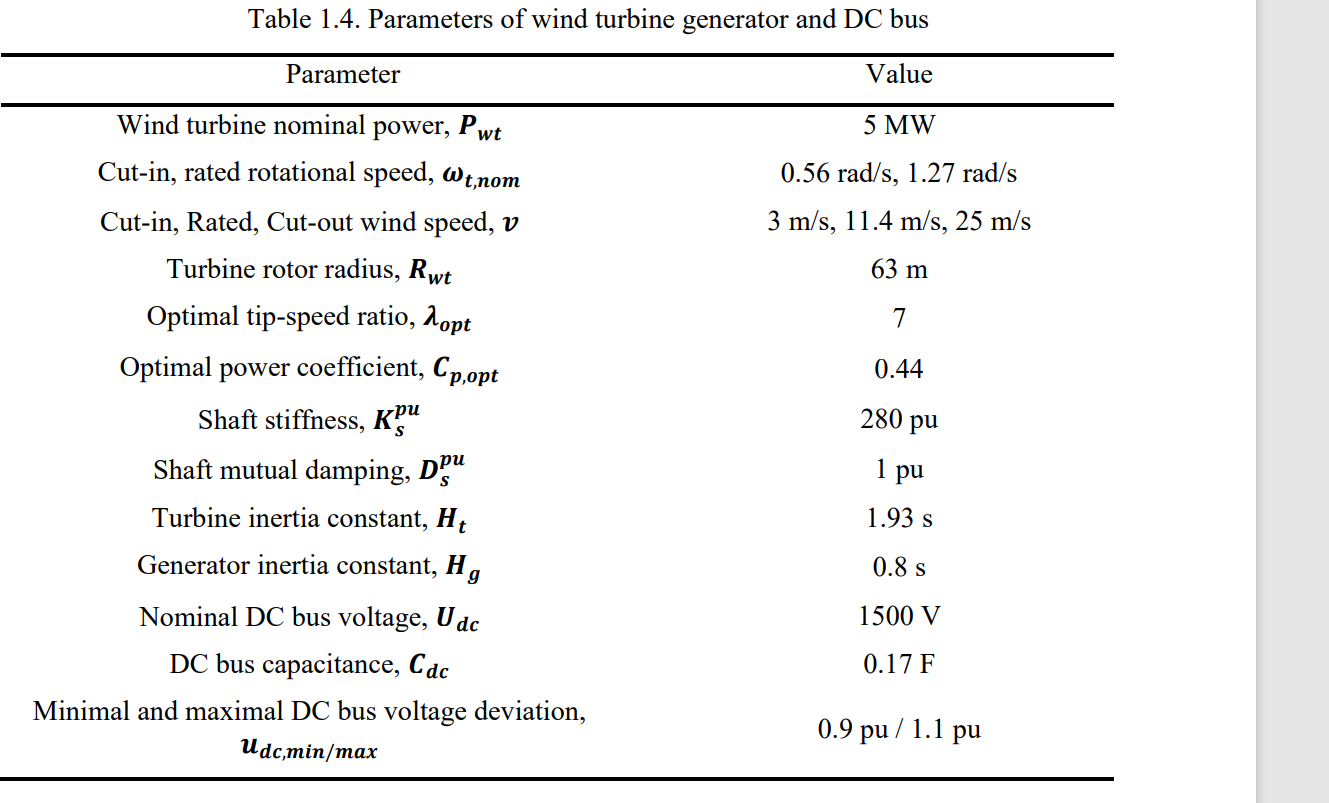

% 
omega_WTR = linspace(0.01,3,100); %*2*pi/60; % rad/s
omega_WTR_n = 1.27 % rad/s

omega_WTR_n = 1.2700

omega_WTR_min = 0.56 % rad/s

omega_WTR_min = 0.5600

R_WTR = 63; % m
v_w = linspace(3,22.8,100);% m/s   11.48;%
v_w_n = 11.4; % m/s
v_w_min = 3; % m/s




lambda = omega_WTR.*R_WTR./v_w%linspace(2,13,50) %

lambda =     0.2100    0.7915    1.3045    1.7606    2.1687    2.5359    2.8682    3.1702    3.4460    3.6989    3.9315    4.1462    4.3449    4.5295    4.7014    4.8618    5.0119    5.1526    5.2847    5.4091    5.5264    5.6371    5.7419    5.8411    5.9353    6.0248    6.1099    6.1909    6.2682    6.3419    6.4124    6.4798    6.5444    6.6062    6.6656    6.7225    6.7773    6.8299    6.8805    6.9293    6.9763    7.0216    7.0653    7.1075    7.1483    7.1877    7.2259    7.2628    7.2985    7.3331


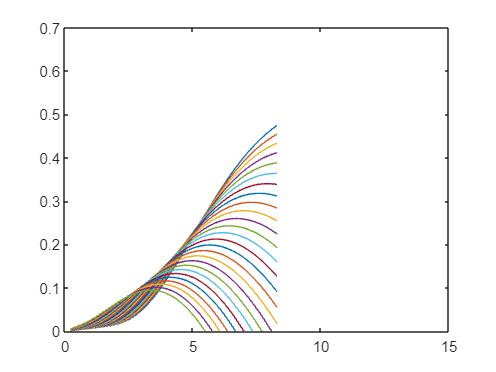

Theta_wr = linspace(0,25,26);

Theta_vw2 = 25;
lambda_opt = 7;

k_aero = -0.008;
c_aero = -0.0035;

v_omega_1 = 0.4; % pu
dpomega1 =0.7 ;
dpv1 = 1.6 ;
dpv2 = -3.5;

% P_wr = 0.5*rho*pi*R_wr^2*v_w^3*
% c_p_vector = zeros(1,length(lambda));
c_p_table = zeros(length(Theta_wr),length(lambda));
for j = 1:length(Theta_wr)
    c_p_vector = zeros(1,length(lambda));
    for i = 1:length(lambda)
        c_p_vector(i) = c_p(Theta_wr(j),lambda(i));
    end
    c_p_table(j,:) = c_p_vector;
    plot(lambda,c_p_vector)
    hold on
end

xlim([0 15])
ylim([0 0.7])
hold off



% initialization

P_aero_0 = 0.6; %p.u.
v_w_0 = 1+(1-0.3)/0.7*(P_aero_0-1) % Initial wind speed

v_w_0 = 0.6000

omega_WTR_0 = lambda_opt*v_w_n/(R_WTR*omega_WTR_n)*v_w_0

omega_WTR_0 = 0.5984

## Mechanical module


H_WTR = 2.5; % s
H_gen = 0.8; % s
c_drt = 1; % pu
k_drt = 280; % pu


## IEA 15 MW reference

% Per unit 
PerUnit

% Aerodynamics
omega_WTR_n = 7.56*2*pi/60 % rad/s here it is the max rotor speed

omega_WTR_n = 0.7917

omega_WTR_min = 5*2*pi/60 % rad/s

omega_WTR_min = 0.5236

R_WTR = 117; % m
v_w_n = 10.59; % m/s
v_w_min = 3; % m/s

Theta_vw2 = 25; % blade angle at twice the retad wind speed
lambda_opt = 9;
C_p_opt = 0.489;

k_aero = -0.008;
c_aero = -0.0035;

v_omega_1 = 0.4; % pu
dpomega1 =0.7 ;
dpv1 = 1.6 ;
dpv2 = -3.5;

P_aero_0 = 0.6; %p.u.
v_w_0 = 1+(1-0.3)/0.7*(P_aero_0-1) % Initial wind speed

v_w_0 = 0.6000

omega_WTR_0 = lambda_opt*v_w_n/(R_WTR*omega_WTR_n)*v_w_0 % Initial rotation

omega_WTR_0 = 0.6174

## Drive train

J_rigid = 3.524605e8;
damping = 4.457e-4;
H_rigid = 0.5*J_rigid*omega_s_m_base/(15e6)

H_rigid = 9.3012

k_drt = damping*T_base/omega_s_m_base

k_drt = 1.1036e+04



H_ratio = 0.3

H_ratio = 0.3000

H_WTR = H_rigid*(1-H_ratio) % s

H_WTR = 6.5108

H_gen = H_rigid*H_ratio % s

H_gen = 2.7904

c_drt = 2; % pu
% k_drt = 280; % pu

## Generator spec

P_rated = 15e6 ;% 

L_d = 0.04444160004/L_s_base; % H divided by Base H
L_q = L_d;
R_a = 0.16/Z_s_base; % Ohm divided by Base Z
psi_pm = 0.1168501600/V_s_base; % Wb divided by base V

X_d = L_d*L_s_base*omega_s_e_base/Z_s_base;

v_t = 1; i_t = 0.6;

% initial values
% power factor
phi = acos(0.5/0.6);
% voltage angle
delta_0 = -atan((X_d*i_t*cos(phi)-R_a*i_t*sin(phi))/(v_t+R_a*i_t*cos(phi)+X_d*i_t*sin(phi)))

delta_0 = -0.2935


v_d0 = v_t*cos(delta_0)

v_d0 = 0.9572

v_q0 = v_t*sin(delta_0)

v_q0 = -0.2893

i_d0 = i_t*cos(delta_0+phi) % pu

i_d0 = 0.5746

i_q0 = i_t*sin(delta_0+phi) % pu

i_q0 = 0.1728

omega_me0 = omega_WTR_0; % pu





c = [0.645 116 0.4 5 21 0.00912 0.08 0.035 0.001]

c =     0.6450  116.0000    0.4000    5.0000   21.0000    0.0091    0.0800    0.0350    0.0010


U = 6

U = 6

omega = 1

omega = 1

R = 63

R = 63

lambda = omega*R/U

lambda = 10.5000

beta=0

beta = 0


a = (-c(4)-c(3)*(2.5+beta)+c(2)*1/(lambda+c(7)*(2.5+beta))-c(8)/(lambda+(2.5+beta)^3))

a = 4.8398

exponent = c(5)*1/(lambda+c(7)*(2.5+beta))-c(8)/(lambda+(2.5+beta)^3)

exponent = 1.9613

cp = c(1)*(c(6)*lambda+a/exp(exponent))+c(9)*lambda

cp = 0.5114

function x = c_p(Theta,lambda)
    % % Fortman
    % c = [0.297 118 -0.50 0.922 1.12 3.33 15.6 0.102 0.017 0.751]';
    % Theta_mark = Theta*c(10);
    % lambda_i = (1/(lambda+c(8)*Theta_mark)-c(9)/(Theta_mark^3+1))^(-1);
    % x = c(1)*(c(2)/lambda_i-c(3)*Theta_mark-c(4)*Theta_mark^(c(5))-c(6))*exp(c(7)/lambda_i);
    % 
    
    % % Mattia
    % c = [0.645 116 0.4 5 21 0.00912 0.08 0.035 0.001];
    % x = c(1)*(c(6).*lambda+(-c(4)-c(3).*(2.5+Theta)+c(2)*1./(lambda+c(7)*(2.5+Theta)-c(8)./(lambda+(2.5+Theta)^3))./(exp(c(5)*(1./(lambda+c(7)*(2.5+Theta)-c(8)./(lambda+(2.5+Theta)^3)))))))+c(9)*lambda;
    % % Johan
    % c = [0.37 151 0.58 0.002 2.14 13.2 -18.4 0.1 0.003 3]';
    % lambda_i = 1./(lambda-c(8)*Theta)-c(9)/(Theta^(c(10))+1);
    % x = c(1)*(c(2)./lambda_i-c(3)*Theta-c(4)*Theta^(c(5))-c(6)).*exp(c(7)./lambda_i);
    % % 'Mattia 2
    c = [0.645 116 0.4 5 21 0.00912 0.08 0.035 0.001];
    a = (-c(4)-c(3)*(2.5+Theta)+c(2)*1/(lambda+c(7)*(2.5+Theta))-c(8)/(lambda+(2.5+Theta)^3));
    exponent = c(5)*1/(lambda+c(7)*(2.5+Theta))-c(8)/(lambda+(2.5+Theta)^3);
    x = c(1)*(c(6)*lambda+a/exp(exponent))+c(9)*lambda;

end